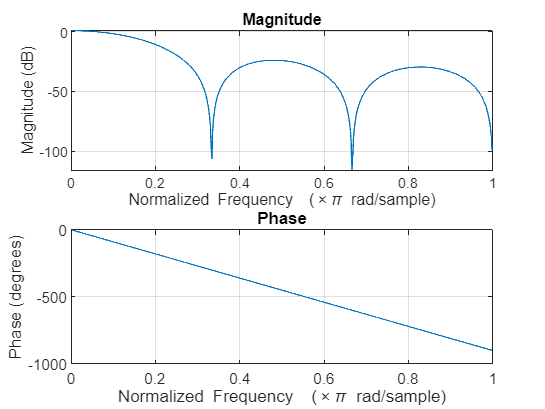

load("ECG3.dat");
% the filter coefficients:
b_lp = 1/32*[1 0 0 0 0 0 -2 0 0 0 0 0 1];
a_lp = [1 -2 1 0 0 0 0 0 0 0 0 0 0 ];
% the frequency and magnitude response:
freqz(b_lp,a_lp);

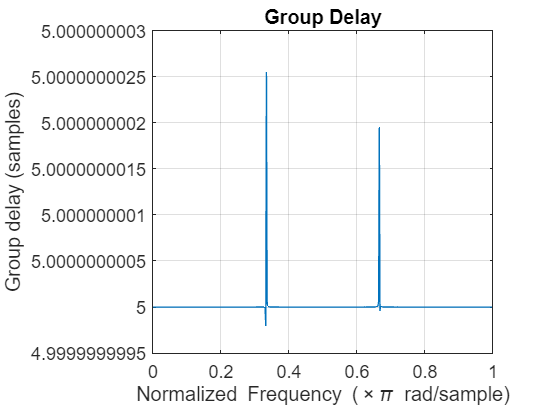

% the delay of the filter:
grpdelay(b_lp, a_lp) % 5 samples

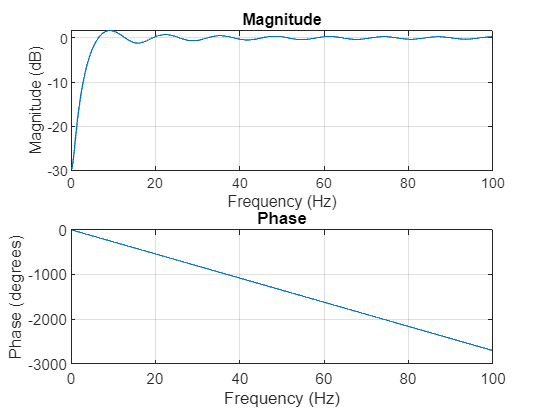


ap_ecg = filter(b_lp,a_lp,ECG3);

b_hp = zeros(1,32); b_hp(1) = -1/32; b_hp(16) = 1; b_hp(17) = -1; b_hp(32) = 1/32;
a_hp = [1 -1];
% the frequency and magnitude response:
freqz(b_hp,a_hp,512,200);

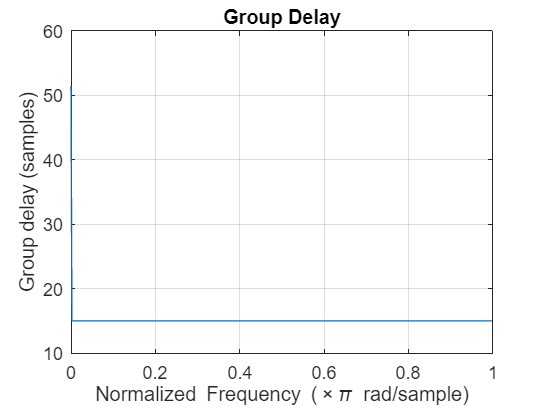

% the delay of the filter:
grpdelay(b_hp, a_hp) % 15 samples (75 ms)


bp_ecg=filter(b_hp,a_hp,ap_ecg);

%plot(bp_ecg)

%derivoidaan
diff_ecg=diff(bp_ecg);

%otetaan neliö
squared_ecg = diff_ecg .^ 2;

%integroidaan
%int_ecg = trapz(0:3999,squared_ecg);

mw_width = round(0.150 * fs); % Window width: 150 ms
mw_filter = ones(1, mw_width) / mw_width;
mwi_signal = conv(squared_ecg, mw_filter, 'same');

time = linspace(0,(1/fs)*3999,3999)

time =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2001    0.2051    0.2101    0.2151    0.2201    0.2251    0.2301    0.2351    0.2401    0.2451


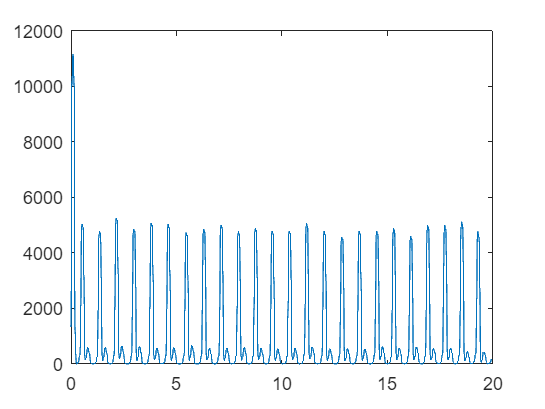

plot(time,mwi_signal)

rr=diff(mwi_signal)

Error using diff
Difference order N must be a positive integer scalar.

vali=mean(rr)